# rojTop view plot

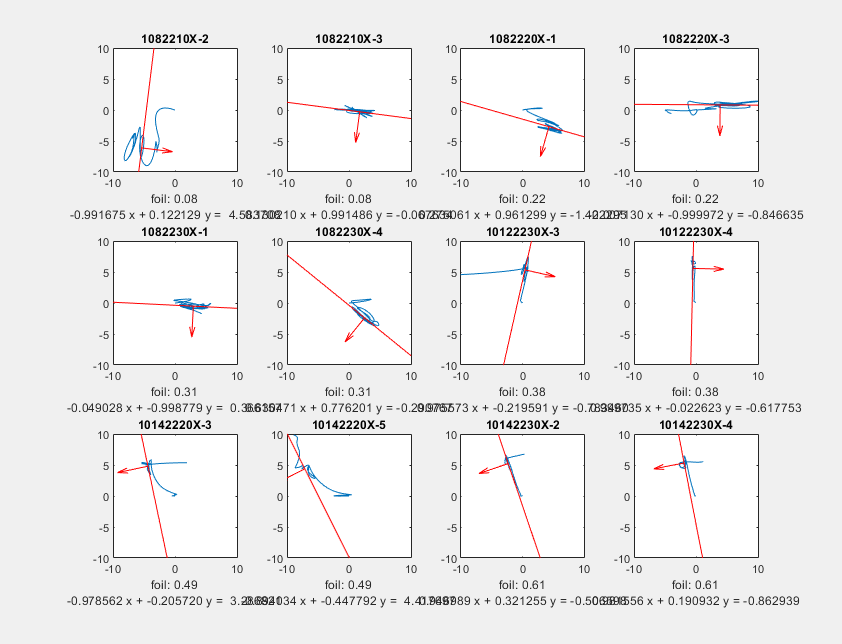

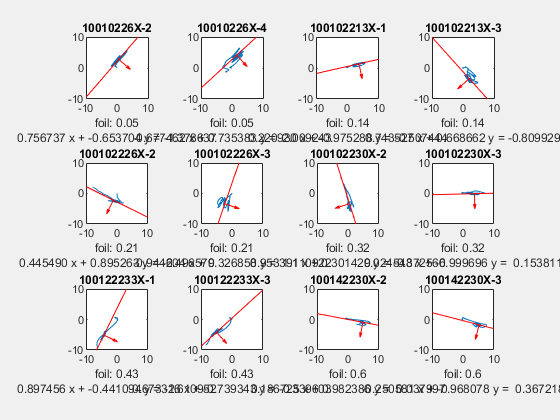

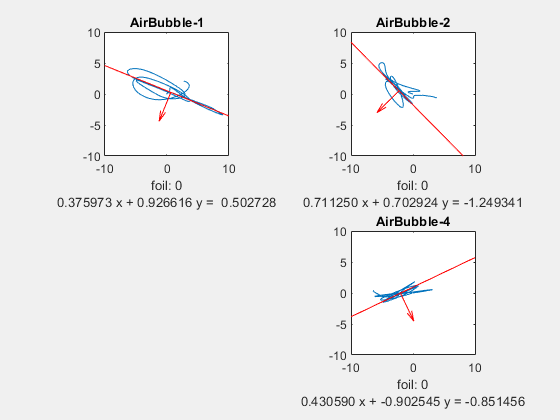

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
        % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        ax(i) = subplot(3,4,i);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        hold on;
        quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('10_oil_TopViewTraj.fig')
figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
       % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        subplot(3,4,i-12);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        hold on;
        quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('100_oil_TopViewTraj.fig')
figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
         % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        subplot(2,2,i-24);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        hold on;
        quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('Air_TopViewTraj.fig')

## Sideview projection plot

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = Plane(3);
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
        yV = [0, -1];
        theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
        if -1/AntiSlope/LengthUnit < 0
            theta = -theta
        end
        ax(i) = subplot(3,4,i);
        plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        xlim([-10, 10]);
        ylim([-10, 10]);
        zlim([0, 200]);
        view(theta, 0);
        title(FileName{i});
    end
end

theta = -7.4817

theta = -15.9677

theta = -0.4085

theta = -2.8103

theta = -39.0853

theta = -78.1278

theta = -63.3952

theta = -71.2611

theta = -78.9923

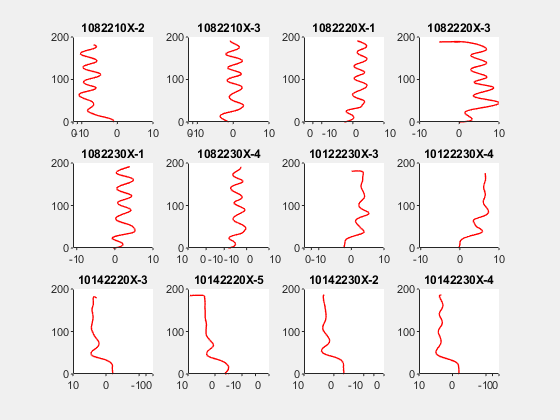

savefig('BestPlaneView10Oil.fig')

figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = Plane(3);
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
        yV = [0, -1];
        theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
        if -1/AntiSlope/LengthUnit < 0
            theta = -theta
        end
        ax(i) = subplot(3,4,i - 12);
        plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        xlim([-10, 10]);
        ylim([-10, 10]);
        zlim([0, 200]);
        view(theta, 0);
        title(FileName{i});
    end
end

theta = -48.0346

theta = -26.4553

theta = -72.4549

theta = -10.7620

theta = -14.5122

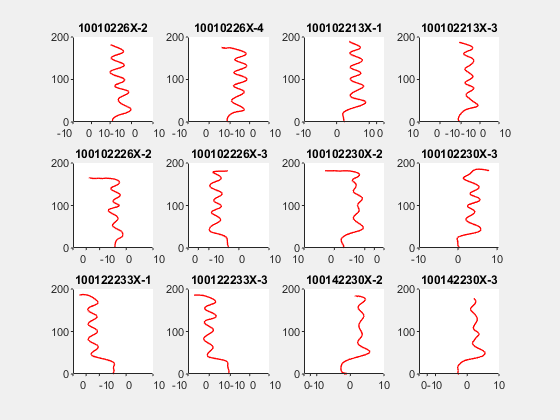

savefig('BestPlaneView100Oil.fig')

figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = Plane(3);
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
        yV = [0, -1];
        theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
        if -1/AntiSlope/LengthUnit < 0
            theta = -theta
        end
        ax(i) = subplot(2,2,i - 24);
        plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        xlim([-10, 10]);
        ylim([-10, 10]);
        zlim([0, 200]);
        view(theta, 0);
        title(FileName{i});
    end
end

theta = -22.0848

theta = -45.3373

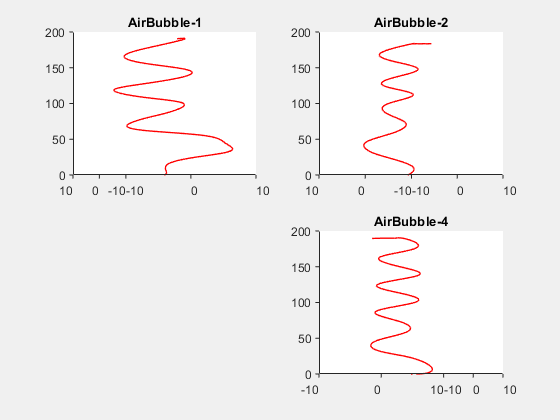

savefig('BestPlaneViewAir.fig')

## Velocity analysis

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(3,4,i);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('Velocity10oil.fig')
saveas(gcf,'Velocity10oil.png')
figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(3,4,i-12);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('Velocity100oil.fig')
saveas(gcf,'Velocity100oil.png')
figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(2,2,i-24);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('VelocityAir.fig')
saveas(gcf,'VelocityAir.png')

## Transverse speed analysis

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('TransverseSpeed10oil.fig')

figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i-12);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('TransverseSpeed100oil.fig')

figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(2,2,i-24);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('TransverseSpeedAir.fig')


## Vertical Velocity

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
foilPlot = []; W = []; error = []; totalSpeed = []; totalError = [];
for i = 1:2:12
    path1 = [ReadingPath, FileName{i}, '.mat'];
    path2 = [ReadingPath, FileName{i + 1}, '.mat'];
    if isfile(path1)
        data = load(path1);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal1 = mean(Total);
        u1 = mean(w);
    end
    if isfile(path2)
        data = load(path2);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal2 = mean(Total);
        u2 = mean(w);      
    end
    uCenter = (u1 + u2)/2;
    range = abs(u1 - u2);  
    foilPlot = [foilPlot, foil(i)];
    W = [W, uCenter];
    error = [error, range];
    tCenter = (meanTotal1 + meanTotal2)/2;
    tRange = abs(meanTotal2 - meanTotal1);
    totalSpeed = [totalSpeed, tCenter];
    totalError = [totalError, tRange];
end
errorbar(foilPlot,W,error);
hold on;
errorbar(foilPlot,totalSpeed, totalError);
hold off;
xlabel('oil fraction');
ylabel('Vertical Speed (mm/s)');
ylim([150,250]); xlim([0, 0.7]);
savefig('VerticalV10Oil.fig')

figure('visible','on');
clf;
foilPlot = []; W = []; error = [];totalSpeed = []; totalError = [];
for i = 13:2:24
    path1 = [ReadingPath, FileName{i}, '.mat'];
    path2 = [ReadingPath, FileName{i + 1}, '.mat'];
    if isfile(path1)
        data = load(path1);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal1 = mean(Total);
        u1 = mean(w);
    end
    if isfile(path2)
        data = load(path2);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal2 = mean(Total);
        u2 = mean(w);      
    end
    uCenter = (u1 + u2)/2;
    range = abs(u1 - u2);  
    foilPlot = [foilPlot, foil(i)];
    W = [W, uCenter];
    error = [error, range];
    tCenter = (meanTotal1 + meanTotal2)/2;
    tRange = abs(meanTotal2 - meanTotal1);
    totalSpeed = [totalSpeed, tCenter];
    totalError = [totalError, tRange];
end
errorbar(foilPlot,W,error);
hold on;
errorbar(foilPlot,totalSpeed, totalError);
hold off;
xlabel('oil fraction');
ylabel('Vertical Speed (mm/s)');
ylim([150,250]); xlim([0, 0.7]);
savefig('VerticalV100Oil.fig')

## Wavelet

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
freq10 = [];
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i);
        %cwt(Tspeed,200);
        [ift,t] = instfreq(Tspeed,200);
        instfreq(Tspeed,200);
        freq = mean(ift);
        freq10 = [freq10, freq];
        xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(foil(i))]});
    end
end
savefig('freq10oil.fig')
figure('visible','on');
clf;
freq100 = [];
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i - 12);
        %cwt(Tspeed,200);
        [ift,t] = instfreq(Tspeed,200);
        instfreq(Tspeed,200);
        freq = mean(ift);
        freq100 = [freq100, freq];
        xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(foil(i))]});
    end
end
savefig('freq100oil.fig')
figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(2,2,i - 24);
        %cwt(Tspeed,200);
        [ift,t] = instfreq(Tspeed,200);
        instfreq(Tspeed,200);
        freq = mean(ift);
        xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(foil(i))]});
    end
end
savefig('freqAir.fig')

figure('visible','on');
clf;
foil10 = [0.08, 0.22, 0.31, 0.38, 0.49, 0.61];
foil100 = [0.05, 0.14, 0.21, 0.32, 0.43, 0.6];
freq10mean = [];
freq100mean = [];
for i = 1:6
    index = i*2 - 1;
    freq10mean = [freq10mean, (freq10(index) + freq10(index + 1))/2];
    freq100mean = [freq100mean, (freq100(index) + freq100(index + 1))/2];
end
plot(foil10, freq10mean, 'r*');
hold on;
plot(foil100, freq100mean, 'bo');
hold on;

[population2,gof] = fit(foil10',freq10mean','poly2');
plot(population2', 'r');
hold on;
[population2,gof] = fit(foil100',freq100mean','poly2');
plot(population2, 'b');


xlabel('oil fraction');
ylabel('freq');
legend('oil10', 'oil100', 'fit curve oil10', 'fit curve oil 100');
xlim([0,0.65]);
savefig('freqCompare.fig')


figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i-12);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('WaveLet100oil.fig')

figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(2,2,i-24);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('WaveLetAir.fig')


## transverse position amplitude

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane; a = Plane(1); b = Plane(2); d = Plane(3);
        x0 = 0; y0 = (d - a * x0) / b;
        x1 = 1; y1 = (d - a * x1) / b;
        vector = [x0,y0;x1,y1];
        for k = 1:length(traj3D)
            q = traj3D(k,1:2);
            p = proj(vector,q);
            traj3D(k,1:2) = p;
        end
        x = traj3D(:,1);
        y = traj3D(:,2);
        Tdistance = sqrt(x.^2 + y.^2);
        for k = 1:length(Tdistance)
            if x(k) < x(1)
                Tdistance(k) = -Tdistance(k) ;
            end
        end
        t = [1:length(Tdistance)]*5;
        z = traj3D(:,3);
        Tdistance = Tdistance - Tdistance(1);
        subplot(3,4,i);
        if i <=6
%             plot(t,Tdistance);
%             title(FileName{i});
%             xlim([0,1000]);
%             ylim([-20,20]);
            [f, P1] = findAmplitude(Tdistance(50:end), 200);
            plot(f,P1);
            ylim([0,2]);
            xlabel(['Use FFT find amplitude: ', num2str(max(P1(f>3))), 'mm']);
            ylabel('transverse distance (mm)')
            title(FileName{i});
        else
            plot(t,Tdistance);
            title(FileName{i});
            xlim([0,1000]);
            ylim([-20,20]);
            xlabel('The amplitude is changing, just plot trajectory in 2d plane')
            ylabel('transverse distance (mm)')
        end
    end
end

savefig('TransversePositionAmplitude10oil.fig')
figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane; a = Plane(1); b = Plane(2); d = Plane(3);
        x0 = 0; y0 = (d - a * x0) / b;
        x1 = 1; y1 = (d - a * x1) / b;
        vector = [x0,y0;x1,y1];
        for k = 1:length(traj3D)
            q = traj3D(k,1:2);
            p = proj(vector,q);
            traj3D(k,1:2) = p;
        end
        x = traj3D(:,1);
        y = traj3D(:,2);
        Tdistance = sqrt(x.^2 + y.^2);
        for k = 1:length(Tdistance)
            if x(k) < x(1)
                Tdistance(k) = -Tdistance(k) ;
            end
        end
        t = [1:length(Tdistance)]*5;
        z = traj3D(:,3);
        Tdistance = Tdistance - Tdistance(1);
        subplot(3,4,i - 12);
        if i <=22
%             plot(t,Tdistance);
%             title(FileName{i});
%             xlim([0,1000]);
%             ylim([-20,20]);
            [f, P1] = findAmplitude(Tdistance(50:end), 200);
            plot(f,P1);
            ylim([0,2]);
            xlabel(['Use FFT find amplitude: ', num2str(max(P1(f>3))), 'mm']);
            ylabel('transverse distance (mm)')
            title(FileName{i});
        else
            plot(t,Tdistance);
            title(FileName{i});
            xlim([0,1000]);
            ylim([-20,20]);
            xlabel('The amplitude is changing, just plot trajectory in 2d plane')
            ylabel('transverse distance (mm)')
        end
    end
end

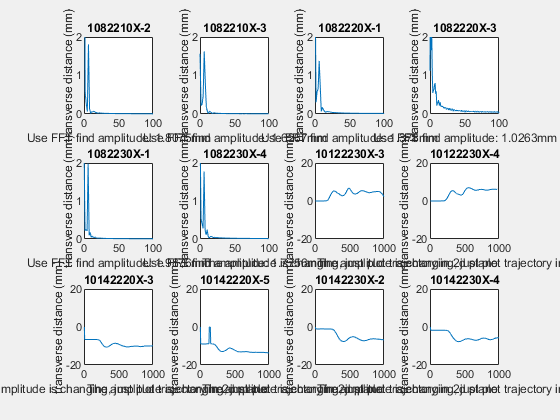

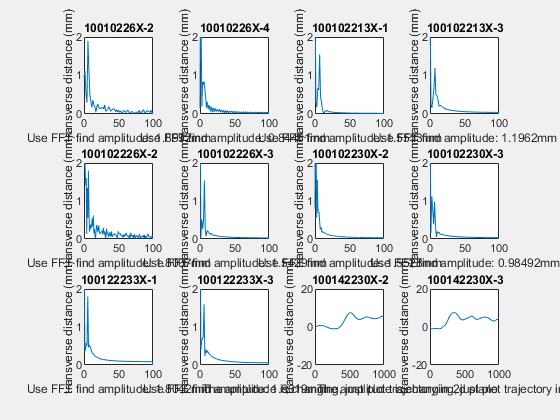

savefig('TransversePositionAmplitude100oil.fig')

figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane; a = Plane(1); b = Plane(2); d = Plane(3);
        x0 = 0; y0 = (d - a * x0) / b;
        x1 = 1; y1 = (d - a * x1) / b;
        vector = [x0,y0;x1,y1];
        for k = 1:length(traj3D)
            q = traj3D(k,1:2);
            p = proj(vector,q);
            traj3D(k,1:2) = p;
        end
        x = traj3D(:,1);
        y = traj3D(:,2);
        Tdistance = sqrt(x.^2 + y.^2);
        for k = 1:length(Tdistance)
            if x(k) < x(1)
                Tdistance(k) = -Tdistance(k) ;
            end
        end
        t = [1:length(Tdistance)]*5;
        z = traj3D(:,3);
        Tdistance = Tdistance - Tdistance(1);
        subplot(2,2,i - 24);
        if i <=28
%             plot(t,Tdistance);
%             title(FileName{i});
%             xlim([0,1000]);
%             ylim([-20,20]);
            [f, P1] = findAmplitude(Tdistance(50:end), 200);
            plot(f,P1);
            ylim([0,2]);
            xlabel(['Use FFT find amplitude: ', num2str(max(P1(f>3))), 'mm']);
            ylabel('transverse distance (mm)')
            title(FileName{i});
        else
            plot(t,Tdistance);
            title(FileName{i});
            xlim([0,1000]);
            ylim([-20,20]);
            xlabel('The amplitude is changing, just plot trajectory in 2d plane')
            ylabel('transverse distance (mm)')
        end
    end
end

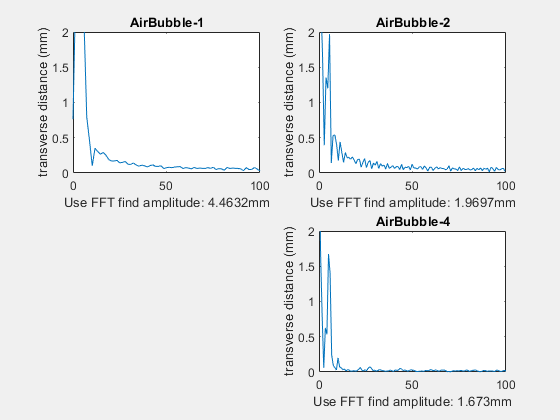

savefig('TransversePositionAmplitudeAir.fig')

function [ProjPoint] = proj(vector, q)
    p0 = vector(1,:);
    p1 = vector(2,:);
    a = [-q(1)*(p1(1)-p0(1)) - q(2)*(p1(2)-p0(2)); ...
        -p0(2)*(p1(1)-p0(1)) + p0(1)*(p1(2)-p0(2))]; 
    b = [p1(1) - p0(1), p1(2) - p0(2);...
        p0(2) - p1(2), p1(1) - p0(1)];
    ProjPoint = -(b\a);
end
function [f, P1] = findAmplitude(X, Fs)
    L = length(X);
    Y = fft(X);
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
end